## A walk through of our code

I cannot replicate our previous results, so I want to walk through our previous code to see what is wrong.

Since then the code is different?

According to my memmory, there might be two crux points.

- The change of the parameter bound. The most important part of the model is $e_{\text{tot}} = \text{conv}( \text{img})$  $\rightarrow$$d(\theta) = \frac {e_{\text{tot}}(\theta)} { 1 + \lambda \text{std}( e_{\text{tot}} )$ $\rightarrow$ $s = \sum_{\theta} d(\theta)$ $\rightarrow$ $\text{pred} = g * s ^n$. In the late Oct, on a phone call with, we changed the bound for parameters space. This might be one reason.

- The other reason is we also changed the calculation of E. Is this the reason?

My outline of debuging is:

Try to add sanity check as each of these variables: $e_{\text{tot}}$, $d(\theta)$, $s$, $\text{pred}$. I have done that before, if the sanity check meet my memory, which means this part is correct. 

Meanwhile, I would read or rewrite the codes

%% Init

close all; clc

Here I need to note that the way I arrange this projec as 

StdProject---

        --- Data

            --- fitResults

            --- Stimuli

            --- fMRIdata

                 --- dataset0x

                      --- v_mean

        --- stdVisualModel (git)

             --- functions (This is a new functions, for the purpose of tidying up the code)

        --- update_note (*where we are right now)

So I need to achieve the path to Data. 

I also found Jon's path is slightly different from mine.    

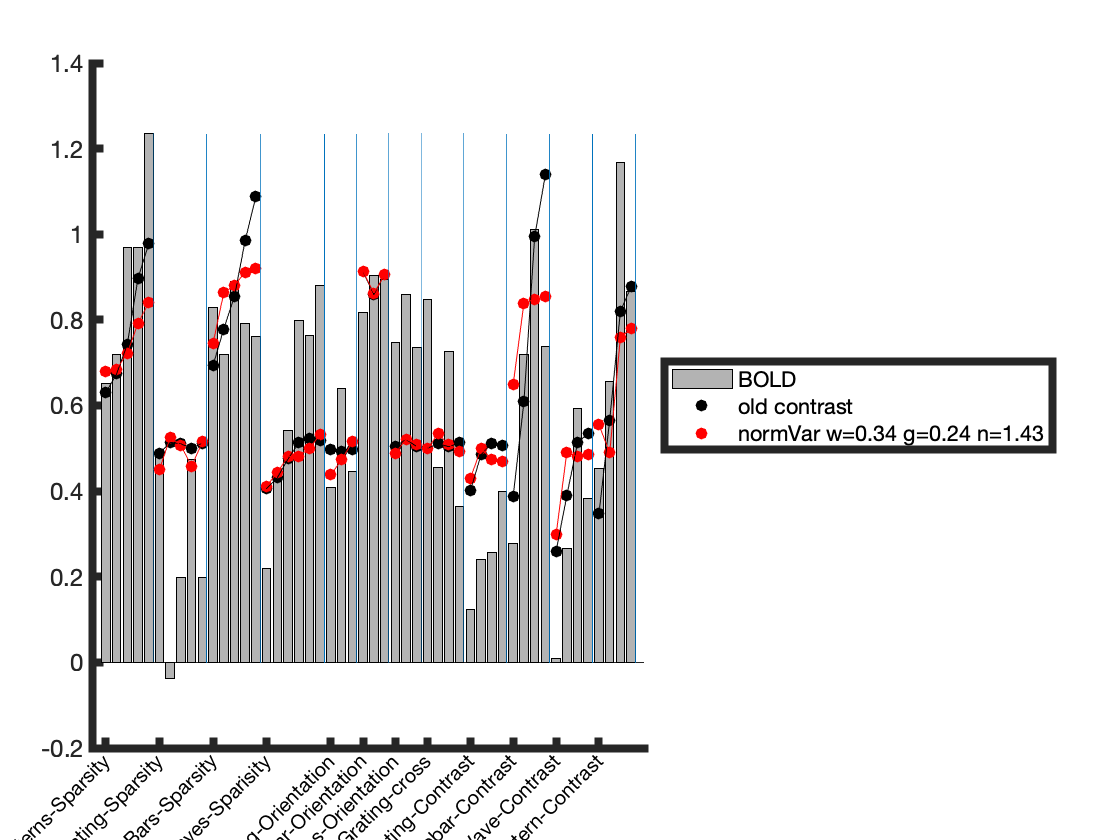

[curPath, prevPath] = stdnormRootPath();
% path to the raw data and stimuli 
addpath( genpath( fullfile( prevPath, 'Data', 'fMRIdata')))

addpath( genpath( fullfile( prevPath, 'Data', 'Stimuli')))
addpath( genpath( fullfile( prevPath, 'Data', 'E')))
% path to the function
addpath( genpath( fullfile( curPath, 'functions' )))
addpath( genpath( fullfile( curPath, 'models' )))
addpath( genpath( fullfile( curPath, 'plot_tools' )))

## Function: dataloader 

See the dataloader function at functions/dataloader.

The function needs to input the following variable

- path: usually we can use the PrevPath, because data are usually stored beyond this github folder level.

- type of data: what kinds of the data you want to load. 1) 'BOLD_target', fMRI data; 2) 'BOLD_pred', prediction data of the model; 3) 'param', fitted parameters; 4) 'Rsquare; 5) 'E_ori' sum over energy across space dim;  6) 'E_xy' sum over ervery across orientation.

- dataset: which dataset : 1, 2, 3, 4

- roi: 1, 2, 3

- model: 1): 'contrast'; 2): 'normStd'; 3): 'normVar'; 4): 'normPower'; 5) 'SOC'; 6) 'ori_surround'.

- New or Old: we do not need to care much about that. just ignore.

dataset = 1;
roi = 2;

loss1 = 0.0446

BOLD_target = dataloader( prevPath, 'BOLD_target', dataset, roi, model, 'old');

loss2 = 0.0428

## Function: plot_BOLD

see the plot_BOLD function at plot_tools

I edit this function to imitate the sklearn function.

The function needs to input the following variable:

- BOLD_pred: the prediction of the model. If we only want to plot fMRI, just put []

- BOLD_taget: fMRI BOLD signal

- dataset

- roi 

- legend: can be []

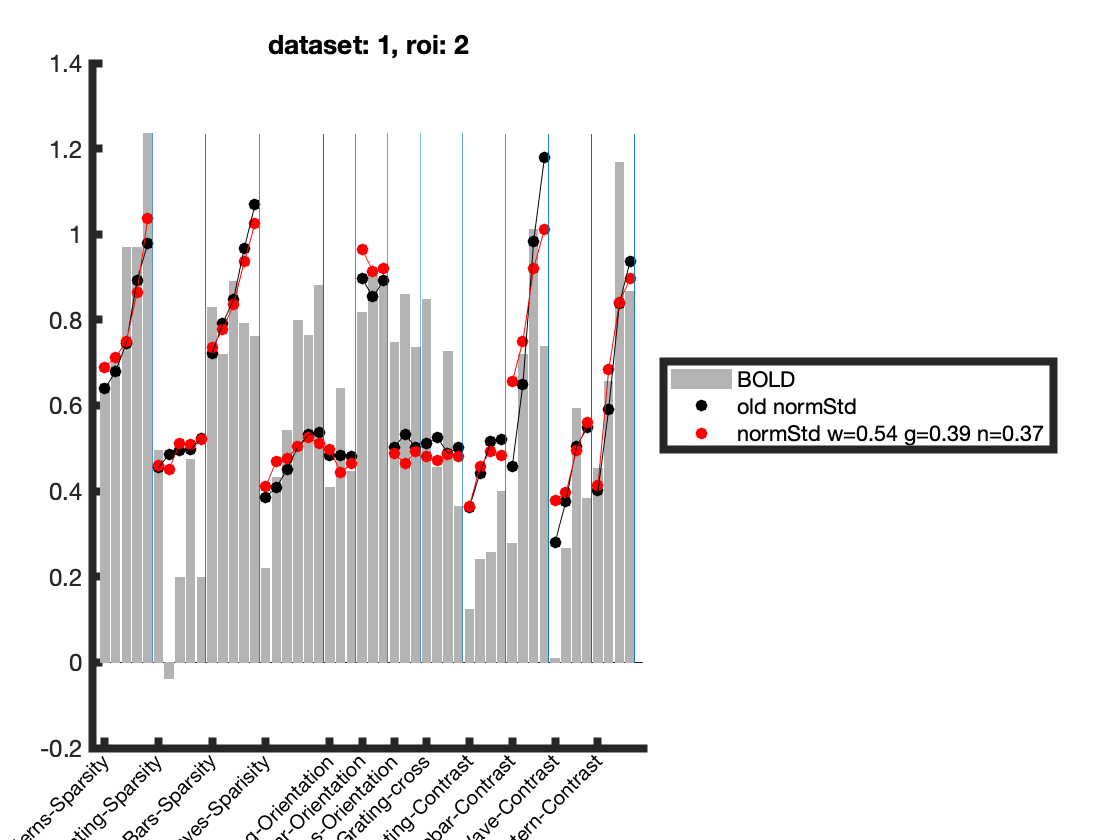

% exmaple 1: only plot BOLD_target
figure;
plot_BOLD( [], BOLD_target, dataset, roi, []);

title('dataset 1, roi: v2')
% example two: plot BOLD prediction + BOLD target
model = 1; %contrast model
figure;
BOLD_pred = dataloader( prevPath, 'BOLD_pred', dataset, roi, model, 'old');
plot_BOLD( BOLD_pred', BOLD_target, dataset, roi, 'contrast',[]);
title('dataset 1, roi: v2, model: contrast' )

## Big problem, now we can have a look at the problem we have from $e_{\text{tot}}\rightarrow \text{pred}$

Here we can have a direct comparsion between the old fitted result and the new one.

dataset = 1;
roi     = 2;
model   = 3;

BOLD_prediction = dataloader( prevPath, 'BOLD_pred', dataset, roi, model, 'old');
target_data = dataloader( prevPath, 'BOLD_target', dataset, roi, [], 'old');

loss1 = 0.0484

BOLD_old = BOLD_prediction;

loss2 = 0.0443

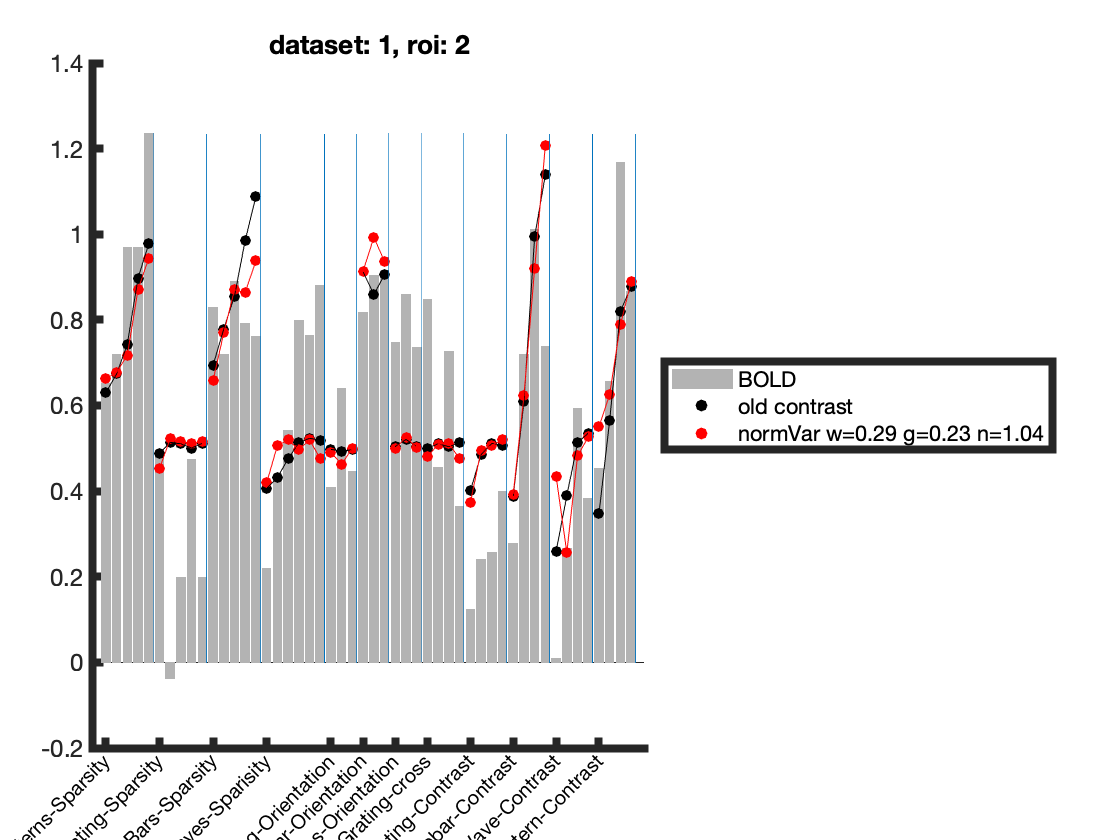

BOLD_prediction = dataloader( prevPath, 'BOLD_pred', dataset, roi, model, 'new');
BOLD_new = BOLD_prediction;
lenPred = size(BOLD_new, 2);

combine_BOLD = NaN(lenPred, 2);
combine_BOLD(:, 1) = BOLD_old';
combine_BOLD(:, 2) = BOLD_new';

figure;
plot_BOLD( combine_BOLD, target_data, 1, 2, {'BOLD', 'old', 'new'}, []);
title( 'This is a comparison: OLD vs NEW')

If we jave a look at the paramters, we can have a better intuition.

The new fitting is extremely unstable across different validations. 

## Breif summary of the observations of the problem:

- Contrast information is lost

- The fitted parameters across validation are not stable. 

One way to understand it is to fix the paramters and to see the value of $e_{\text{tot}}$ and $\text{var}( e_{\text{tot}})$. It might be after we resize the image, the variable change too much. Makinng it easier to stuck at the local minima.

The solution will be found through making new function.

## Models: contrast model

see more detial at models/contrastModel

This is a class, with the following internal functions:

- contrastModel: initialization, mainly define the bound and fit time. change it in a new model 

- foward: which is the core function, usually to add a new model we only need to edit this. To use it: model. fit( model, input, target, verbose, cross_validation )

- fixparameters: fix the input params as the default parameters of the model: model.fixparameters( model, param)

- predict: predict with default parameters: model.predict( model, E_ori )

- metric: output Rsquare: model.metric( BOLD_pred, BOLD_target )

- loss_fn: MSE: model.loss_fn( param, model, E_ori, BOLD_traget )

- optim: optimization: bads

- fit: fit the model with cross_validation.

%% init the model
model_std = normStdModel(40);
%% fit with cross_validation 
[losses_std, BOLD_pred_std, params_std, Rsquare_std, model_std] = model_std.fit( model_std, E_ori, BOLD_target, 'off', 'cross_valid' );

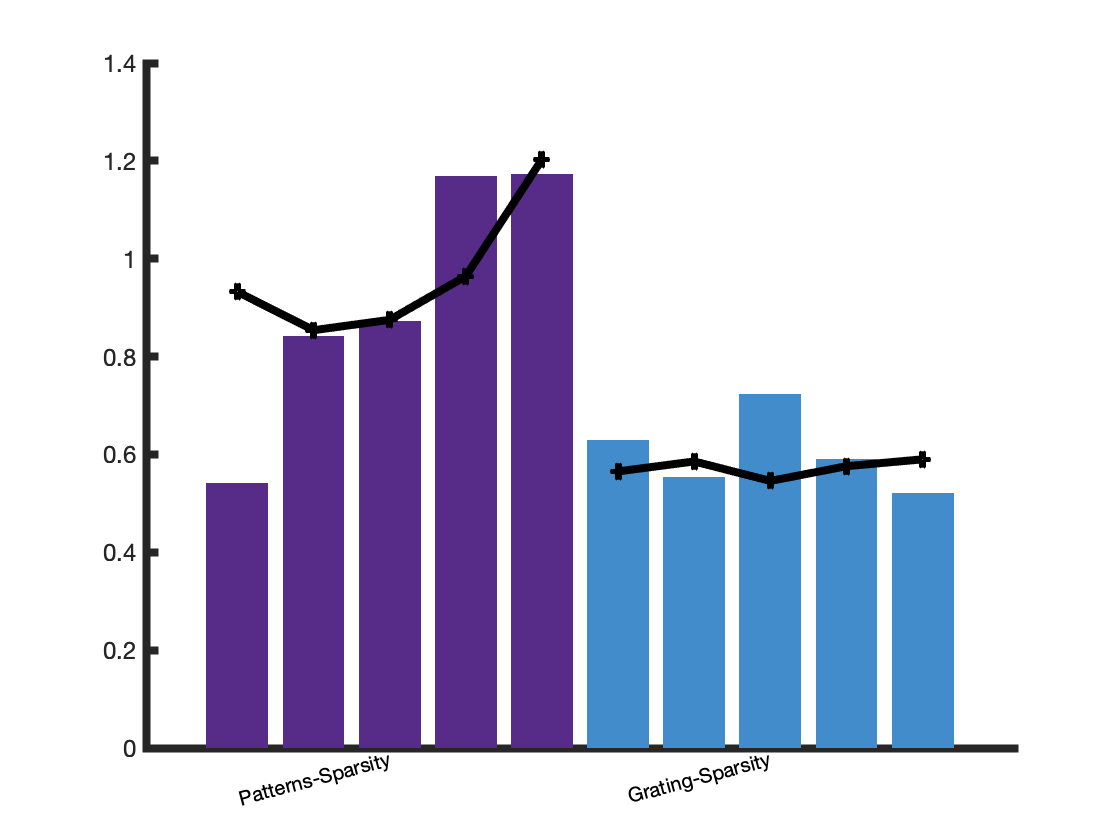

model_idx = 2;
combine_BOLD = NaN(lenPred, 2);
figure;
BOLD_old_std = dataloader( prevPath, 'BOLD_pred', dataset, roi, model_idx, 'old');
combine_BOLD(:, 1)= BOLD_old_std;
combine_BOLD(:, 2) = BOLD_pred_std;
loss1 = mse( BOLD_pred_std, BOLD_target )
loss2 = mse( BOLD_old_std, BOLD_target )

figure;
plot_BOLD( combine_BOLD, BOLD_target, dataset, roi, {'BOLD', 'old normStd', model_std.legend}, [])
title( 'dataset: 1, roi: 2')


model_var= normVarModel(40);
%% fit with cross_validation 
[losses_var, BOLD_pred_var, params_var, Rsquare_var, model_var] = model_var.fit( model_var, E_ori, BOLD_target, 'off', 'cross_valid' );

model_idx = 3;
combine_BOLD = NaN(lenPred, 2);
figure;
BOLD_old_var = dataloader( prevPath, 'BOLD_pred', dataset, roi, model_idx, 'old');
combine_BOLD(:, 1)= BOLD_old_var;
combine_BOLD(:, 2) = BOLD_pred_var;
loss1 = mse( BOLD_pred_var, BOLD_target )
loss2 = mse( BOLD_old_var, BOLD_target )

plot_BOLD( combine_BOLD, BOLD_target, dataset, roi, {'BOLD', 'old contrast', model_var.legend})
title( 'dataset: 1, roi: 2')

## Focus on target Stimuli:

In the new code, the code of prediction and fit is totally independent of the input. 

So what we only need to edit, is the plot_BOLD function

% load the data with dataloader
dataset = 1;
roi = 2; 
model_idx = 2;
stim_vector = 1:10;
BOLD_target = dataloader( prevPath, 'BOLD_target', dataset, roi );
E_ori = dataloader( prevPath, 'E_ori', dataset, roi );
E_ori  = E_ori(:, :, stim_vector);
BOLD_target = BOLD_target( stim_vector );
model2_std = normVarModel( 60 );
[loss1, BOLD2_pred_std, params2_std, Rsquare2_std, model2_std] = model2_std.fit( model2_std, E_ori, BOLD_target, 'off', 'cross_valid' );

figure;
plot_BOLD( BOLD2_pred_std', BOLD_target, dataset, roi, {'BOLD', 'std'}, false )

